% Step 1: Load the fisheriris dataset
clc
clear
load fisheriris.mat

% Step 2: Extract the feature matrix X and class labels y
X = meas; % Feature matrix (150 samples x 4 features)
y = species; % Class labels (setosa, versicolor, virginica)

% Step 3: Split the data into training and testing sets
rng('default'); % For reproducibility
cv = cvpartition(y, 'Holdout', 0.3); % 70% training, 30% testing
X_train = X(training(cv), :);
y_train = y(training(cv));
X_test = X(test(cv), :);
y_test = y(test(cv));

## Reduce dimensionality with LDA

% Step 4: Apply LDA for dimensionality reduction on the training data
num_components = 2; % Number of components in the reduced space
lda_model = fitcdiscr(X_train, y_train); % Fit the LDA model
[eigenvectors, eigenvalues] = eig(lda_model.BetweenSigma, lda_model.Sigma);
[~, sorted_indices] = sort(diag(eigenvalues), 'descend');
projection_matrix = eigenvectors(:, sorted_indices(1:num_components));

% Step 5: Project training and testing data onto the LDA components
X_train_reduced = X_train * projection_matrix;
X_test_reduced = X_test * projection_matrix;

num_neighbours = 5;
kNN_model_LDA = fitcknn(X_train_reduced,y_train, 'NumNeighbors', num_neighbours, 'Standardize', 1);

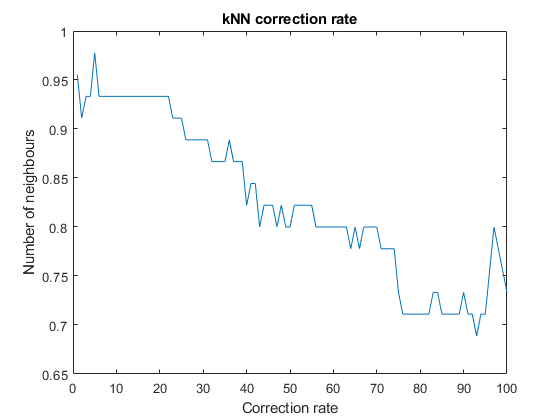

for i = 1:100
    kNN_model_LDA.NumNeighbors = i;
    y_pred = predict(kNN_model_LDA, X_test_reduced);
    conf = confusionmat(y_test, y_pred);
    correction_rate(i) = sum(diag(conf))/sum(conf,"all");
end
[M, I] = max(correction_rate);
plot(1:100, correction_rate)
title('kNN correction rate');
xlabel('Correction rate');
ylabel('Number of neighbours');

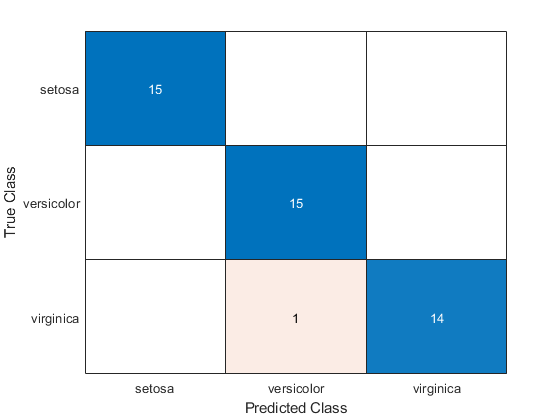


kNN_model_LDA.NumNeighbors = I;
y_pred = predict(kNN_model_LDA, X_test_reduced);
C = confusionmat(y_test, y_pred);
confusionchart(y_test, y_pred);

disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

    15     0     0
     0    15     0
     0     1    14



correction_rate = sum(diag(C))/sum(C,"all");
% print('results/kNN_confchart_iris', '-dpng', '-r600')

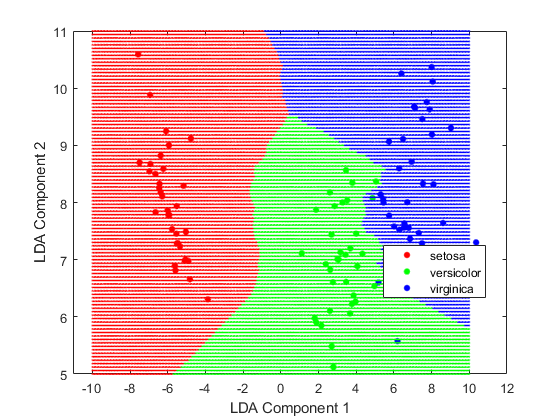

gscatter(X_train_reduced(:, 1), X_train_reduced(:, 2), y_train, 'rgb');
xlabel('LDA Component 1');
ylabel('LDA Component 2');

[L, W] = meshgrid(linspace(-10, 10, 500), linspace(5,11,100)); ...
L = L(:);
W = W(:);
pred = kNN_model_LDA.predict([L W]);
hold on;
h = gscatter(L, W, pred, 'rgb', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
xlabel('LDA Component 1');
ylabel('LDA Component 2');
legend('setosa', 'versicolor', 'virginica', '', '', '');
hold off; 

% print('results/kNN_visual_iris', '-dpng', '-r600')

## Plot results

### Plot colours

% Plot colours
orange = '#FF9A5B';
blue   = '#06ACE9';
purple = '#7E2F8E';
green = '#77AC30';
cyan = '#4DBEEE';
maroon = '#A2142F';
black = '#000000';

### Plot style

% Plot style
line_width = 2;

[y_pred_kNN, scores_kNN, cost_kNN] = predict(kNN_model_LDA, X_test_reduced);

[y_pred_LDA, scores_LDA, cost_LDA] = predict(lda_model, X_test);

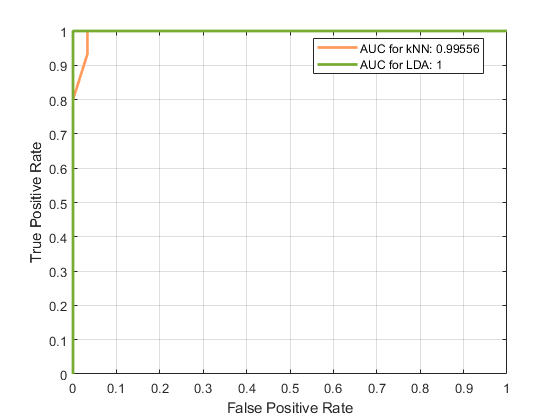



% Convert the labels to binary for ROC curve analysis (1: Positive, others: Negative)
current = 'versicolor';
labels_binary_kNN = y_test;
labels_binary_kNN_num(1:length(labels_binary_kNN)) = 0;
labels_binary_kNN_num(strcmpi(labels_binary_kNN,current)) = 1;
labels_binary_kNN_num(labels_binary_kNN_num ~= 1) = 0;
labels_binary_kNN_num = labels_binary_kNN_num';
sum_scores_kNN = sum(scores_kNN(:, [1, 3:end]), 2);

% Calculate the ROC curve and AUC for kNN kernel
[X_roc_kNN, Y_roc_kNN, ~, AUC_kNN] = perfcurve(labels_binary_kNN_num, scores_kNN(:, 2), 1);

% Convert the labels to binary for ROC curve analysis (1: Positive, others: Negative)
labels_binary_LDA = y_test;
labels_binary_LDA_num(1:length(labels_binary_LDA)) = 0;
labels_binary_LDA_num(strcmpi(labels_binary_LDA,current)) = 1;
labels_binary_LDA_num(labels_binary_LDA_num ~= 1) = 0;
labels_binary_LDA_num = labels_binary_LDA_num';

sum_scores_LDA = sum(scores_LDA(:, [1, 3:end]), 2);

% Calculate the ROC curve and AUC for LDAnomial kernel
[X_roc_LDA, Y_roc_LDA, ~, AUC_LDA] = perfcurve(labels_binary_LDA_num, scores_LDA(:, 2), 1);

% Plot the ROC curves for both kernels
figure;
plot(X_roc_kNN, Y_roc_kNN, '-', 'LineWidth', line_width, 'Color', orange);
hold on;
plot(X_roc_LDA, Y_roc_LDA, '-', 'LineWidth', line_width, 'Color', green);
xlabel('False Positive Rate');
ylabel('True Positive Rate');
% title('ROC Curves for kNN and LDA models');
legend(['AUC for kNN: ', num2str(AUC_kNN)], ['AUC for LDA: ', num2str(AUC_LDA)], 'Location', 'Best');
grid on;
hold off;


print('results/kNN_visual_iris', '-dpng', '-r600')